**LHC**

For the LHC data, we are going to have to fake a background. Make a Poisson background with mean 100. 

background_dist = makedist('Poisson', "lambda", 100);

**Problem 1**

The first problem is to look at your background distribution and determine where the 5*σ*

 sensitivity threshold is. [Hint, you've done this several times now, look back at the first few labs.]

We report the five sigma probability as the probability of being further to the right than 5 sigma from the mean of a normal distribution. To find the 5 sigma threshold in our poisson background, we go to the point where the cumulative probability to the left of that point is equal to the cumulative probability to the left of +5 standard deviations from the mean in a normal distribution:

five_sigma_prob = 1 - normcdf(5)

five_sigma_prob = 2.8665e-07

five_sigma_val = icdf(background_dist, 1-five_sigma_prob)

five_sigma_val = 154

**Problem 2**

Now inject a signal of known strength. You will want to make your signal moderately strong, say somewhere in the 8-30*σ *range. Inject this signal into your background data many times.

First, we generate 100k backgroud values. Then we generate signal value and add it to the background values.

background_values = random(background_dist, 100000, 1);

signal_sigma_value = 8;
signal_value = icdf(background_dist, normcdf(signal_sigma_value));
signal_with_background = background_values + signal_value;

a) Histogram how bright the observed signal appears to be, and discuss it's shape. Say in words what this histogram is telling you.

Unsurprisingly, the shape of the distribution of measured signal is the same as a the background, only shifted up by the signal value. This is unsurprising, given how this data set was constructed. Of note is that this does appear roughly normal in shape. Given that we have a Poisson distribution with a large size parameter, this is unsurprising. It is important to remember that it is still a discrete pdf though, an all the values should be integer differences from the injected signal value. 

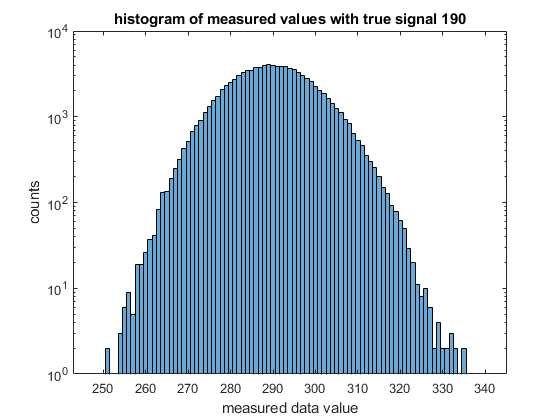


buffer = 3.5;
first_bin_edge = min(signal_with_background) - buffer;
last_bin_edge = max(signal_with_background) + buffer;
bin_edges = first_bin_edge:1:last_bin_edge;

figure
histogram(signal_with_background, 'BinEdges', bin_edges)
title(['histogram of measured values with true signal ' num2str(signal_value)])
xlabel('measured data value')
ylabel('counts')
set(gca, 'YScale', 'log')

b) Is your observed signal biased? (e.g. is the observed value  equally likely to be stronger or weaker than the true injected signal?)  Is it symmetric?

The observed signal is biased! Because our background is positive semi-definite, we expect that the measured signal will always be at least as large as the true signal. In more specifics, because the size parameter of our Poisson background is large, we expect almost all of the background to be significantly larger than zero (in this case we say significant as the majority of the background signal is on the same order as the signal value). The observed signal is fairly symmetric around the sum of the mean of the background and the injected signal. As mentioned earlier, the pdf for a Poisson with a large mean value is similar in shape to a Gaussian of the same mean and variance. We will use this fact to help motivate how to inject signals of 30*σ *in the next problem.

**Problem 3**

Now make a suite of injected signals. You will want to have a range  of injected signal strengths, starting at zero and extending well above 5*σ *(30*σ *or more). You will want to follow the work you did for Homework 5 very closely.

a) Clearly state what you are simulating, and make a 2D histogram of injected signal vs. observed data

I am injecting a range of signal values. Because this is supposed to model LHC data, and the number of detections of a certain kind is an integer number, I am just going to inject the same number of samples at each integer signal from 0 to 400. 

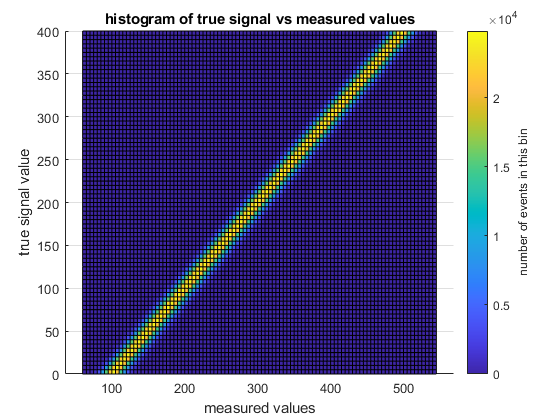

min_signal_val = 0;
max_signal_val = 400;
number_of_signal_vals = (max_signal_val - min_signal_val) + 1;
total_number_of_points = 10000000;
points_per_signal = round(total_number_of_points/number_of_signal_vals);

total_number_of_points = points_per_signal*number_of_signal_vals;

true_signal = floor ( (0:1:total_number_of_points-1)/ points_per_signal );
background = random(background_dist, 1, total_number_of_points);

measured_signal = true_signal + background;

edges_x = min(measured_signal(:)):5:max(measured_signal(:));
edges_y = min_signal_val:5:max_signal_val;
edges = {edges_x edges_y};

figure;
hist3([measured_signal', true_signal'], 'Edges', edges,'CDataMode','auto', 'FaceColor', 'interp');
c = colorbar;
c.Label.String = 'number of events in this bin';
title('histogram of true signal vs measured values');
xlabel(['measured values']);
ylim([min_signal_val,max_signal_val])
ylabel(['true signal value']);
view(2)

b) For the same injected signal power as in problem 2, show that you get the same answer.

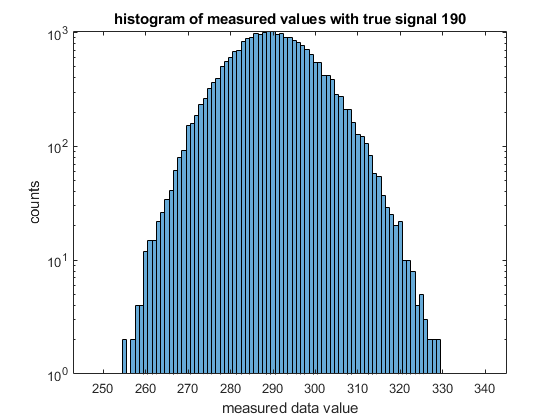

idx = find(true_signal == signal_value);
measured_data = measured_signal(idx);

figure
histogram(measured_data, 'BinEdges', bin_edges)
title(['histogram of measured values with true signal ' num2str(signal_value)])
xlabel('measured data value')
ylabel('counts')
set(gca, 'YScale', 'log')

c) Now reverse the problem, select an observed data value (pick something quite a bit stronger than 5*σ*) and create a 1D histogram of the true signal probability given the observed data. Describe the meaning of this histogram.

This histogram is the true signals that generated a single measured value.

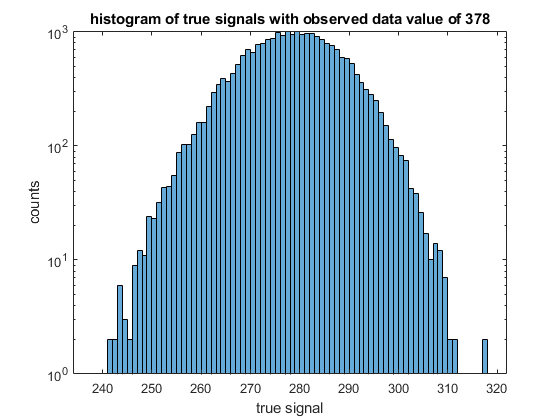

observed_data_value = 378;

idx = find(measured_signal == observed_data_value);
corresponding_true = true_signal(idx);

figure
signal_for_fixed_observed_hist = histogram(corresponding_true);
title(['histogram of true signals with observed data value of ' num2str(observed_data_value)])
xlabel('true signal')
ylabel('counts')
set(gca, 'YScale', 'log')

d) For your observed signal, what is the 1*σ* uncertainty on the true signal strength?

I will do this both experimentally and theoretically. First experimentally I will find the mean of the above histogram and include points out symmetrically from there until a fraction equivalent to the area within 1 standard deviation of a normal distribution are included:

mean_true_val = mean(corresponding_true(:))

edges_less_than_mean = signal_for_fixed_observed_hist.BinEdges < mean_true_val;
edges_less_than_mean_idx = find(edges_less_than_mean);
edges_greater_than_mean = signal_for_fixed_observed_hist.BinEdges > mean_true_val;
edges_greater_than_mean_idx = find(edges_greater_than_mean);
mean_bin_front_edge_idx = edges_less_than_mean_idx(end);
mean_bin_back_edge_idx = edges_greater_than_mean_idx(1);



steps = min(mean_bin_front_edge_idx-1, length(signal_for_fixed_observed_hist.Values) - mean_bin_front_edge_idx);
number_included = zeros(1, steps+1);

for step = 0:steps
    range = mean_bin_front_edge_idx-step:mean_bin_front_edge_idx+step;
    number_included(1+step) = sum(signal_for_fixed_observed_hist.Values(range));
end

fraction_included = number_included / sum(signal_for_fixed_observed_hist.Values(:));

one_sigma_prob = normcdf(1) - normcdf(-1);

at_least_one_sigma = fraction_included > one_sigma_prob;

idx = find(at_least_one_sigma);

range_min = signal_for_fixed_observed_hist.BinEdges(mean_bin_front_edge_idx) - idx(1)

range_min = 267

range_max = signal_for_fixed_observed_hist.BinEdges(mean_bin_front_edge_idx) + idx(1) + 1

range_max = 290

We add one in the equation for the max above, as the indexes refer to the left edge of the bins included. We see that in this data set it is not perfectly symmetric and have a 1 sigma uncertainty range of [267, 290] around the mean true value of ~278

To find it theoretically, we know that the background has a mean of 100 which is also at the center of the distribution (50 percent of probability under the curve is on either side of that mean). Moving 1/2 the one sigma probability to each side of that center gives use the theoretical range of background values within a 1 sigma range of the mean. Then because we were histogramming true values for a given measured, we subtract those from the given measured. This gives us the expected symmetric 1 sigma uncertainty range of [268, 288] around the mean of 278.

range_min_theory = observed_data_value - icdf(background_dist, 0.5 + 1/2*one_sigma_prob)

range_min_theory = 268

range_max_theory = observed_data_value - icdf(background_dist,0.5 - 1/2*one_sigma_prob)

range_max_theory = 288

e) Discuss the answer to part d in some depth. Is it symmetric? Is it biased? Does this make sense?

The distribution of true signals at a given observed data value is biased and (nearly) symmetric. Because the background for our model here is purely positive, the true signals are always less than or equal to the measured signal. In this case, because the Poisson background mean is so high, all of our observed data points are larger than our true signals. Also, because our background Poisson mean is so large, the distribution is roughly symmetric. As discussed in 2b, as you go to large parameters values (>30) the Poisson distribution approaches that of a discrete normal distribution with mean and variance equal to the mean of the Poisson. There is still a slight observable asymmetry in the log plot, where the right hand tail falls off faster than the lefthand tail. Because the probability of having a true value in our injected signal is uniform, the probability of an observed data point coming from a true signal of a given value is simply the same as the probability that the background distribution is equal to their difference. So because our background is a Poisson with a mean of 100, the probability of the true signal value being $s$ when the observed value is $d$ is just the probability that you pull a value of $d-s$ from a Poisson distribution with mean 100: $\frac{100^{d-s} e^{-100}}{(d-s)!}$. Thus we expect the shape of this plotted for fixed observed data point to be that of part b), flipped.